Data = readtable("FlightDataTrun.csv");

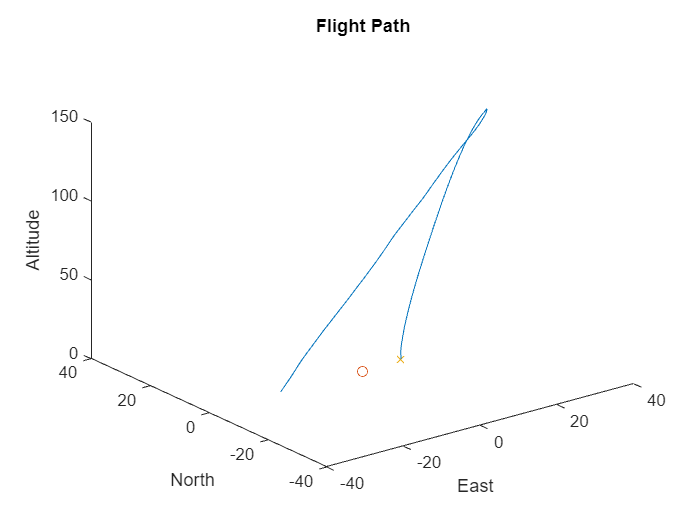


Data.Properties.VariableNames(1) = "Time";
Data.Properties.VariableNames(2) = "Altitude";
Data.Properties.VariableNames(3) = "PositionEastOfLaunch";
Data.Properties.VariableNames(4) = "PositionNorthOfLaunch";
Data.Properties.VariableNames(5) = "RollRate";
Data.Properties.VariableNames(6) = "PitchRate";
Data.Properties.VariableNames(7) = "YawRate";

Data.RollRate(isnan(Data.RollRate)) = 0;
Data.PitchRate(isnan(Data.PitchRate)) = 0;
Data.YawRate(isnan(Data.YawRate)) = 0;

% Data needs to be offset by 10m in the X and 1m in the Z.
% Also in time because I cant get the delay to work in Gazebo
Data.Altitude = Data.Altitude + 1;
Data.PositionEastOfLaunch = Data.PositionEastOfLaunch + 10;
Data.Time = Data.Time + 15;

%Roll rates need to be changed into diff
Data.RollRate(2:end,:) = diff(Data.RollRate);
Data.PitchRate(2:end,:) = diff(Data.PitchRate);
Data.YawRate(2:end,:) = diff(Data.YawRate);

plot3(Data.PositionEastOfLaunch, Data.PositionNorthOfLaunch, Data.Altitude)
hold on
xlabel('East')
ylabel('North')
zlabel('Altitude')
axis([-40 40 -40 40 0, 150])
title('Flight Path')
plot3(0, 0, 0, 'o')
plot3(10, 0, 1, 'x')
hold off

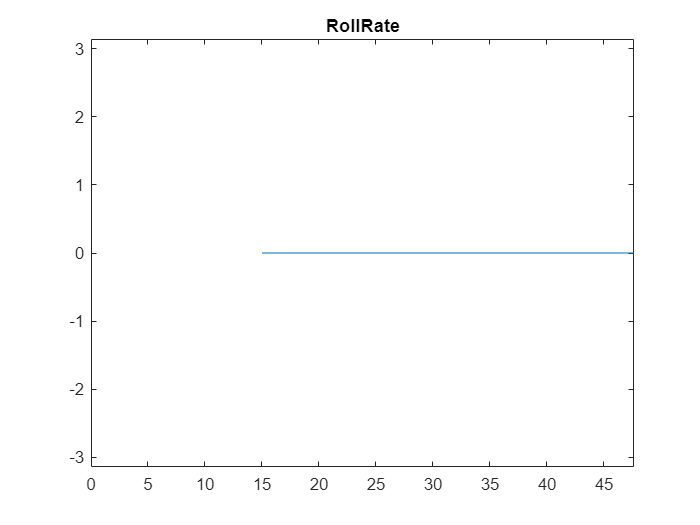


plot(Data.Time,Data.RollRate)
title('RollRate')
axis([0 Data.Time(end) -pi pi])

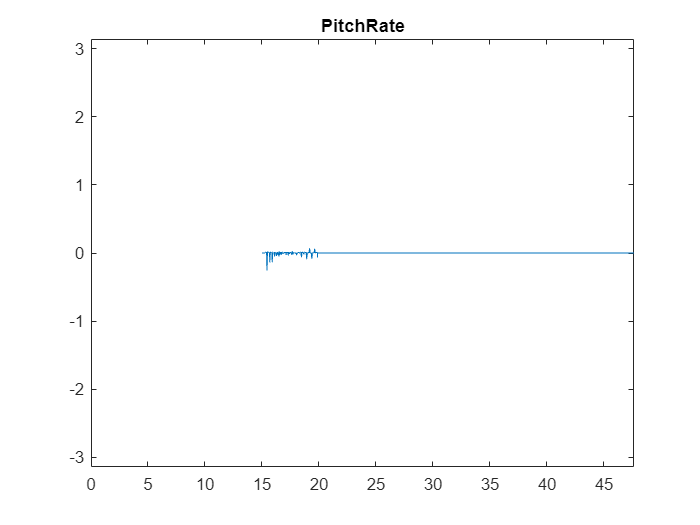

plot(Data.Time,Data.PitchRate)
title('PitchRate')
axis([0 Data.Time(end) -pi pi])

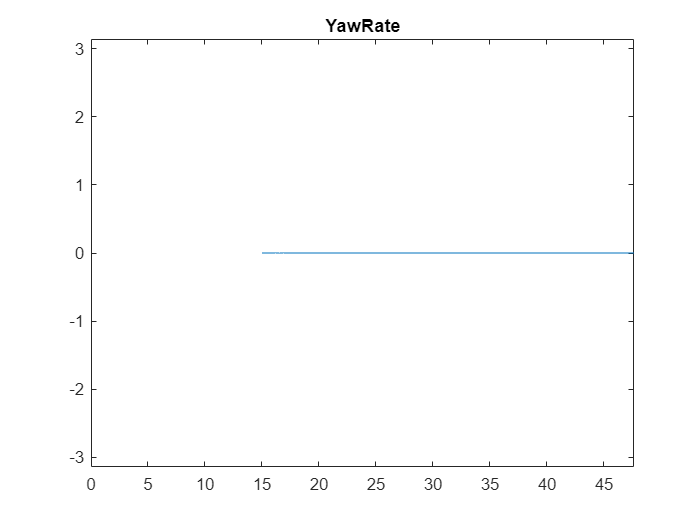

plot(Data.Time,Data.YawRate)
title('YawRate')
axis([0 Data.Time(end) -pi pi])


% Make like this including tabations
%               <waypoint>
%                 <time>0.0</time>
%                 <pose>x y z r p y</pose>
%              </waypoint>
%
% r p y is rotated because of the model, r=yaw p=pitch y=roll 

t5 = '\t\t\t\t\t';
t6 = '\t\t\t\t\t\t';

lb = '\n';

wp = '<waypoint>';
wpc = '</waypoint>';
tm = '<time>';
tmc = '</time>';
ps = '<pose>';
psc = '</pose>';
s = ' ';

fileID = fopen('worldPose.txt','w')

fileID = 3


for i = 1:length(Data.Time)
    string = strcat([t5,wp,lb, ...
                    t6,tm,num2str(Data.Time(i)),tmc,lb, ...
                    t6,ps,num2str(Data.PositionEastOfLaunch(i)), ...
                        s,num2str(Data.PositionNorthOfLaunch(i)), ...
                        ' ',num2str(Data.Altitude(i)), ...
                        ' ',num2str(Data.YawRate(i)), ...
                        ' ',num2str(Data.PitchRate(i)), ...
                        ' ',num2str(Data.RollRate(i)),psc,lb, ...
                    t5, wpc, lb]);
    fprintf(fileID, string);
end

fclose(fileID);